# Discretization of the Advection-Diffusion Equation

clear, clc, close all
set_demo_defaults

Consider the Advection-Diffusion Equations (ADE) for the heat transport by advection and conduction


$$\frac{\partial T}{\partial t} + \nabla\cdot\left(\mathbf{v}\, T - k \nabla T\right) = f_s$$


where we have assumed that $\rho$ and $c_p$ are constant and divided by them, so that $k = \kappa/(\rho c_p)$ is the thermal diffusivity. Using the $\theta$-method and our discrete operators we discretize this equation as follows


$$\mathbf{I}\frac{\mathbf{u}^{n+1} - \mathbf{u}^n}{\Delta t} + \mathbf{D}*(\mathbf{A}(\mathbf{v}) - \mathbf{Kd}*\mathbf{G}) *(\theta \mathbf{u}^{n+1}+(1-\theta)\mathbf{u}^{n+1}) = \mathbf{f}_s$$


Here both the advective and diffusive/conductive terms are treated equally. Let's first consider the purely advective case, $k=0$ and $f_s =0$, so that


$$\mathbf{IM}*\mathbf{u}^{n+1} = \mathbf{EX}*\mathbf{u}^n$$


where implicit and explicit matrices are given by


$$\mathbf{IM} = \mathbf{I} + \Delta t (1-\theta) \mathbf{D}*\mathbf{A}(\mathbf{v})$$



$$\mathbf{EX} = \mathbf{I} - \Delta t\,\theta\,\mathbf{D}*\mathbf{A}(\mathbf{v})$$


here $\mathbf{A}(\mathbf{v})$ is the matrix that computes the upwind flux based on the sign of $\mathbf{v}$. 

v0= 1;
Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 30;
Grid.periodic = 'x-dir';
Grid = build_grid(Grid);
[D,G,~,I,M] = build_ops(Grid);
v = v0*ones(Grid.Nfx,1); A = flux_upwind(v,Grid);
L = D*A; S = I;
IM = @(theta,dt) S + (1-theta)*dt*L;
EX = @(theta,dt) S - theta*dt*L;

## Explicit advective time step restriction (CFL-condition)

Similar to the diffusive case the Forward Euler Method ($\theta =1$) is only conditionally stable. Again we can confirm this by looking at the eigenvalue spectrum of the resulting amplification matrix, $\mathbf{AMP} = \mathbf{IM}^{-1}\mathbf{EX}$. For an advection problem we cannot impose natural boundary conditions, hence we impose periodic BC's - something we have not discussed in class (but not very difficult).

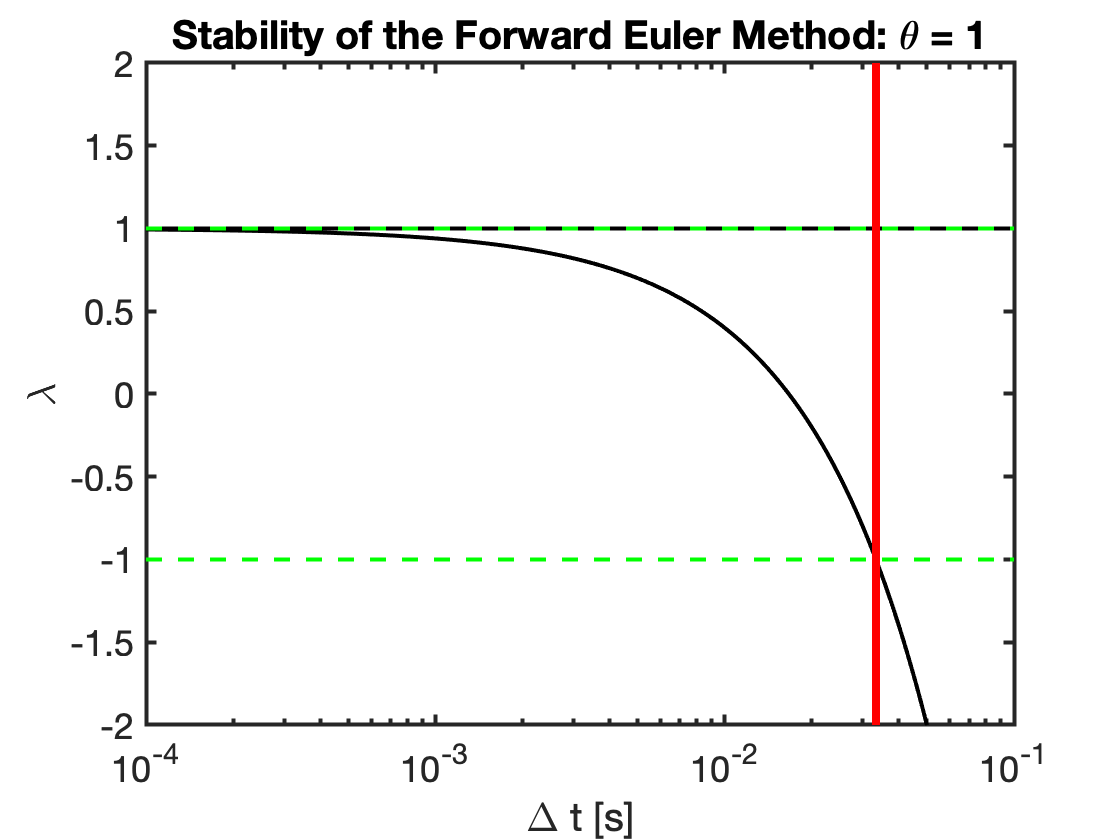

theta = 1;
dt_max = Grid.dx/(v0);
dt_vec = logspace(-4,-1,3e2);

figure
for i = 1:length(dt_vec)
    A = inv(IM(theta,dt_vec(i)))*EX(theta,dt_vec(i));
    lam = eig(full(A));
    lam_max_FE(i) = max(lam);
    lam_min_FE(i) = min(lam);
end
semilogx(dt_vec,lam_max_FE,'k'), hold on
semilogx(dt_vec,lam_min_FE,'k')
semilogx(dt_vec,ones(size(dt_vec)),'g--','linewidth',2)
semilogx(dt_vec,-ones(size(dt_vec)),'g--','linewidth',2)
semilogx(dt_max*[1 1],[-2 2],'r','linewidth',4), hold off
ylim([-2 2])
xlabel '\Delta t [s]'
ylabel('\lambda')
title 'Stability of the Forward Euler Method: \theta = 1'

For $\Delta t > \Delta x/|v|$ the magnitude of the largest eigenvalues exceeds 1 and the method is unstable (red line). This criterion is referred to a the Courant-Friedrichs-Levy condtion or CFL-condition.

## Comparison to Neumann condtion for diffusion

It is worth comparing the explicit time step limits for both diffusion and advection as function of the dimensionless grid size, $\Delta x'=\Delta x/L$, and the Peclet number, $Pe = vL/k$, where $L$ is the domain size. Given the two conditions on the time step $\Delta t_N \leq \Delta x^2/(2 k)$ and $\Delta t_{\mathrm{CFL}} \leq \Delta x/|v|$ we have the ratio


$$\frac{\Delta t_{\mathrm{CFL}}}{\Delta t_{\mathrm{Neu}}} = \frac{2}{\Delta x'\,Pe}$$


so that the explicit timestep is limited by diffusion when $\Delta x' < 2/\mathrm{Pe}$. Therefore, as the grid is refined the time step is always limited by diffusion. In fluid dynamical problems surch as convection in the ice shell, $\mathbf{Pe}\gg1$, so that advection may limit the time step for realistic problems with finite grid size.

## Implicit advective time stepping

Of course, we can also choose the implicit Backward Euler (BE) and Crank-Nicholson Methods (CN) to time step the advection equation. 

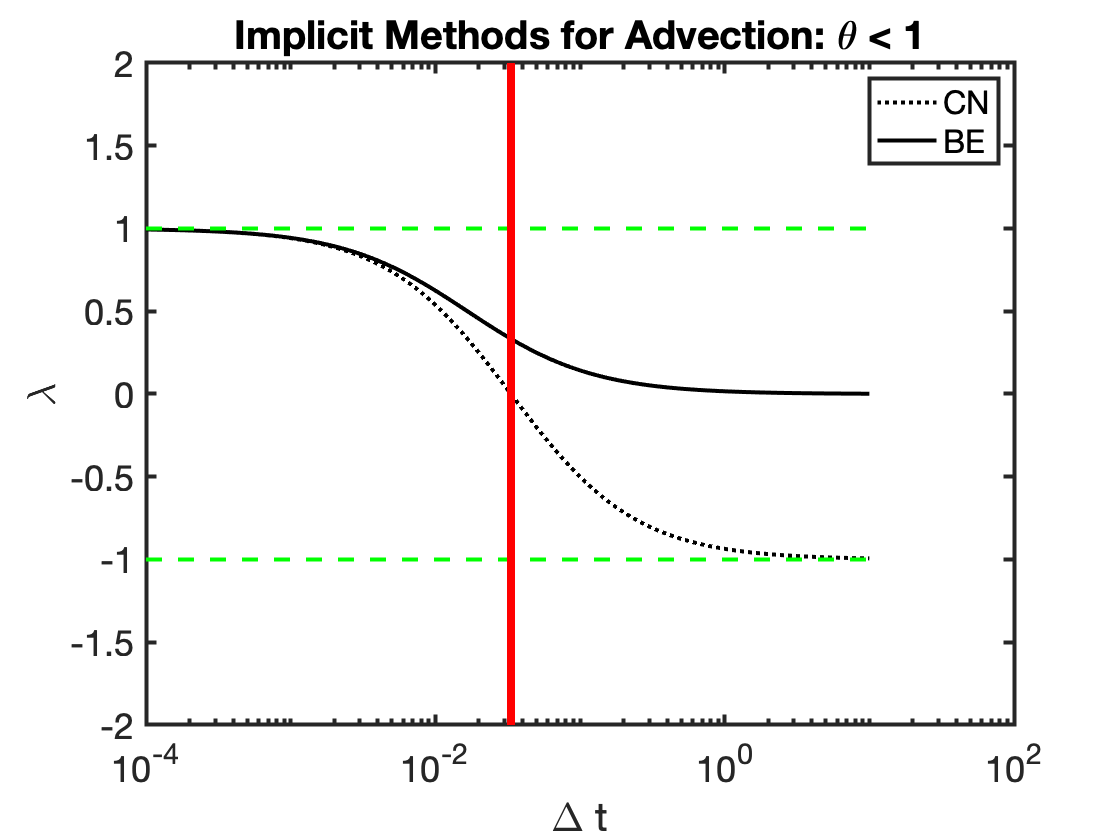

theta = 1;
dt_max = Grid.dx/(v0);
dt_vec = logspace(-4,1,3e2);
lam_max_BE = zeros(length(dt_vec),1);
lam_max_CN = lam_max_BE;
lam_min_BE = lam_max_BE;
lam_min_CN = lam_max_BE;

figure
for i = 1:length(dt_vec)
    theta = 0; % BE
    A = inv(IM(theta,dt_vec(i)))*EX(theta,dt_vec(i));
    lam = eig(full(A));
    lam_max_BE(i) = max(lam);
    lam_min_BE(i) = min(lam);
    
    theta = 0.5; % CN
    A = inv(IM(theta,dt_vec(i)))*EX(theta,dt_vec(i));
    lam = eig(full(A));
    lam_max_CN(i) = max(lam);
    lam_min_CN(i) = min(lam);
end
semilogx(dt_vec,lam_min_CN,'k:'), hold on
semilogx(dt_vec,lam_min_BE,'k')
semilogx(dt_vec,ones(size(dt_vec)),'g--','linewidth',2)
semilogx(dt_vec,-ones(size(dt_vec)),'g--','linewidth',2)
semilogx(dt_max*[1 1],[-2 2],'r','linewidth',4), hold off
ylim([-2 2])
xlabel '\Delta t'
ylabel('\lambda')
title 'Implicit Methods for Advection: \theta < 1'
legend('CN','BE')

## Transient solution

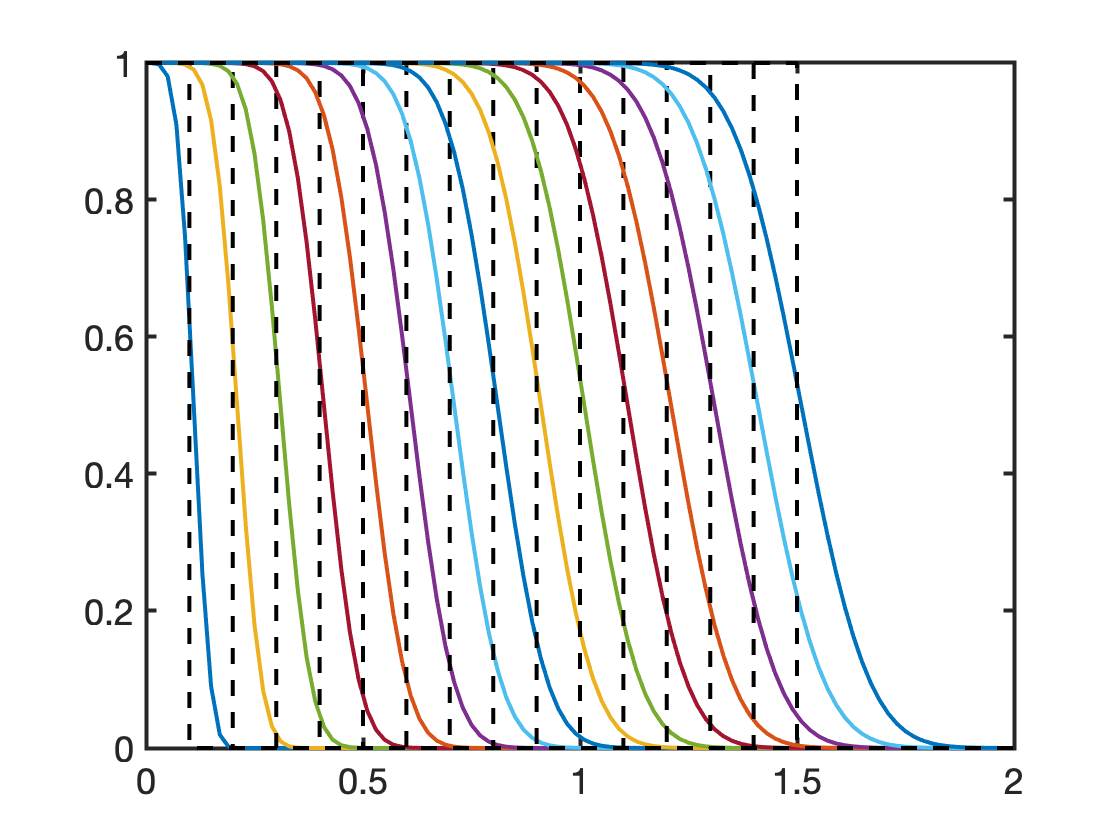

theta = 1;   Nx = 100; Length = 2;  v0 = 1; phi =1;
tmax = 1.5; cfl = .5; 


% Grid and operators
Grid.xmin = 0; Grid.xmax = Length; Grid.Nx = Nx; 
Grid = build_grid(Grid);
[D,G,~,I,M] = build_ops(Grid);
dt = cfl*Grid.dx/(v0);
Nt = round(tmax/dt);
v = v0*ones(Grid.Nfx,1);
A = flux_upwind(v,Grid);

% Assemble implicit and explicit operators
IM = @(theta)  I + (1-theta)*dt/phi*(D*A);
EX = @(theta)  I - theta*dt/phi*(D*A);

% Boundary conditions
BC.dof_dir   = Grid.dof_xmin;
BC.dof_f_dir = Grid.dof_f_xmin;
BC.dof_neu   = [];
BC.dof_f_neu = [];
BC.qb        = [];
BC.g         = 1;
[B,N,fn] = build_bnd(BC,Grid,I);

% Initial conditions
cFE = zeros(Grid.Nx,1);

% Transient solution
figure
time = 0;
for i=1:Nt
    time = time + dt; xf = v0*time;
    %% Finite Volume
    cFE = solve_lbvp(IM(theta),EX(theta)*cFE,B,BC.g,N);
    if mod(i,10) == 0
    plot(Grid.xc,cFE,'-'), hold on
    plot([0 xf xf Grid.xmax],[1 1 0 0],'k--')
    drawnow
    end
end

## Numerical diffusion

The main challence in numerical simulation of advective transport is the elimination of so-called numerical diffusion. The numerical example below illustrates this

theta = 1;   Nx = 100; Length = 2;  v0 = 1; phi =1;
tmax = .5; cfl = .1; 


% Grid and operators
Grid.xmin = 0; Grid.xmax = Length; Grid.Nx = Nx; 
Grid = build_grid(Grid);
[D,G,~,I,M] = build_ops(Grid);
dt = cfl*Grid.dx/(v0);
Nt = round(tmax/dt);
v = v0*ones(Grid.Nfx,1);
A = flux_upwind(v,Grid);

% Assemble implicit and explicit operators
Lim = @(theta)  I + (1-theta)*dt/phi*(D*A);
Lex = @(theta)  I - theta*dt/phi*(D*A);

% Boundary conditions
BC.dof_dir   = Grid.dof_xmin;
BC.dof_f_dir = Grid.dof_f_xmin;
BC.dof_neu   = [];
BC.dof_f_neu = [];
BC.qb        = [];
BC.g         = 1;
[B,N,fn] = build_bnd(BC,Grid,I);

% Initial conditions
cFE = zeros(Grid.Nx,1);
cCN = zeros(Grid.Nx,1);
cBE = zeros(Grid.Nx,1);

% Transient solution
figure
time = 0

time = 0

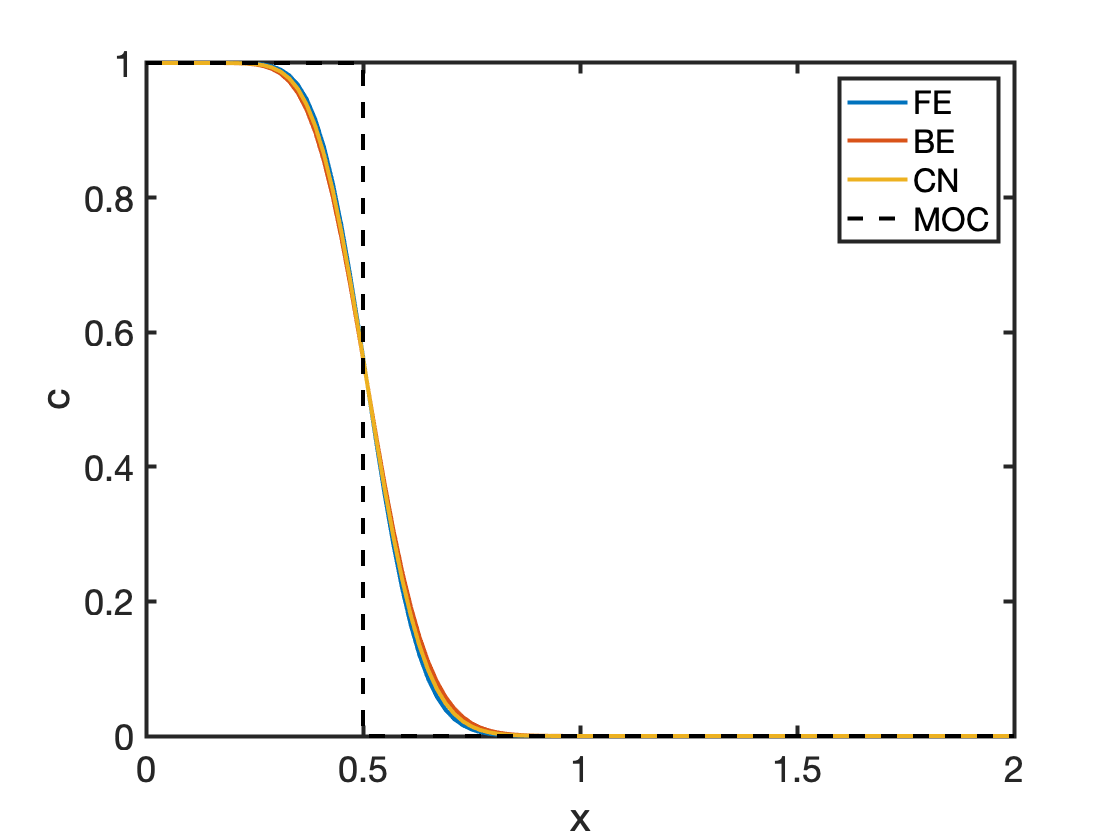

for i=1:Nt
    time = time + dt;
    %% Finite Volume
    cFE = solve_lbvp(Lim(1.0),Lex(1.0)*cFE,B,BC.g,N);
    cCN = solve_lbvp(Lim(0.5),Lex(0.5)*cCN,B,BC.g,N);
    cBE = solve_lbvp(Lim(0.0),Lex(0.0)*cBE,B,BC.g,N);
end
xf = v0*time;
clf
plot(Grid.xc,cFE,'-'), hold on
plot(Grid.xc,cBE,'-')
plot(Grid.xc,cCN,'-')
plot([0 xf xf Grid.xmax],[1 1 0 0],'k--')
xlabel 'x'
ylabel 'c'
legend('FE','BE','CN','MOC')

# Auxillary functions

## Advection-diffusion front

This function evaluates the analytic solution for an advection dffusion front in a semi-infinte half space. This solution matches the constant Dirichlet BC at x=0;

function [u] = ADEfront(x,t,Pe)
u_lowPe = .5*erfc(sqrt(Pe)*(x-t)/2/sqrt(t)) + ...
           .5*erfc(sqrt(Pe)*(x+t)/2/sqrt(t)).*exp(Pe*x);
u_highPe = .5*          erfc(sqrt(Pe)*(x-t)/2/sqrt(t));

% eliminate nan's and inf's from
switch_vec = isnan(u_lowPe) + isinf(u_lowPe);
u_highPe(switch_vec==0) = 0;
u_lowPe( switch_vec==1) = 0;

u = u_lowPe + u_highPe;
end